Problem 3. Tight-binding chain

First, construct MPO.

function Hs = tb_chain_MPO(L, t)
    id = eye(2);
    c  = [0 1; 0 0];     % annihilation operator

    Hs = cell(1,L);

    for i = 1:L
        if i < L
            tl = t(i);
        else
            tl = 0;
        end

        W = zeros(2,2,4,4);

        W(:, :, 1, 1) = id;
        W(:, :, 2, 1) = c;
        W(:, :, 3, 1) = c';
        W(:, :, 4, 2) = -tl * c';
        W(:, :, 4, 3) = -tl * c;
        W(:, :, 4, 4) = id;

        Hs{i} = W;
    end

    Hs{1} = Hs{1}(:, :, end, :); %첫번째 Hamiltonian chain 3번 leg dummy로
    Hs{end} = Hs{end}(:, :, :, 1); %마지막 Hamiltonian chain 4번 leg dummy로
end

Then set the parameters, and set the t list(hopping coefficient) for sub-problem a, b, and c.

 % DMRG parameter
N_sweep = 5;
L = 40;
physical_dim = 2;
N_keep_list = [30, 40, 50, 60, 70]; 

l = 1:L-1;
t_a = ones(size(l));  
t_b = 1.2.^(-(l-1));
t_c = 2 * rand(size(l)) - 1;
% 3 different hopping coefficient list

For sub-problem a, let's set the MPO.

MPO = tb_chain_MPO(L, t_a);

Now, a figure is plotted for the case of MPS by iterative diagonalization and 1 site update.

figure;
hold on;
for i = 1 : 5
    N_keep = N_keep_list(i);
    fprintf('Nkeep value : %d', N_keep);
    [M, E_G1, E_list] = my_dmrg(MPO, N_keep, N_sweep, 0, 1, L, physical_dim); %MPS by iterative diagonalization, 1 site update dmrg
    [E_G2,d_G,e_1p] = nonIntTB (-t_a);
    Error_list = abs(E_list(end, :)- E_G2);
    plot(1:N_sweep*2, Error_list, 'DisplayName', ['Nkeep :', num2str(N_keep)]);
end

Nkeep value : 30

25-05-20 14:05:55 | Sweep #1 of 10 (right -> left) : Energy = -25.10765
25-05-20 14:05:55 | Sweep #2 of 10 (left -> right) : Energy = -25.10779
25-05-20 14:05:55 | Sweep #3 of 10 (right -> left) : Energy = -25.10779
25-05-20 14:05:55 | Sweep #4 of 10 (left -> right) : Energy = -25.10779
25-05-20 14:05:55 | Sweep #5 of 10 (right -> left) : Energy = -25.10779
25-05-20 14:05:55 | Sweep #6 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:05:56 | Sweep #7 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:05:56 | Sweep #8 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:05:56 | Sweep #9 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:05:56 | Sweep #10 of 10 (left -> right) : Energy = -25.1078


Nkeep value : 40

25-05-20 14:05:56 | Sweep #1 of 10 (right -> left) : Energy = -25.10771
25-05-20 14:05:57 | Sweep #2 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:05:57 | Sweep #3 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:05:57 | Sweep #4 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:05:57 | Sweep #5 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:05:57 | Sweep #6 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:05:57 | Sweep #7 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:05:58 | Sweep #8 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:05:58 | Sweep #9 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:05:58 | Sweep #10 of 10 (left -> right) : Energy = -25.1078


Nkeep value : 50

25-05-20 14:05:58 | Sweep #1 of 10 (right -> left) : Energy = -25.10775
25-05-20 14:05:59 | Sweep #2 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:05:59 | Sweep #3 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:05:59 | Sweep #4 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:05:59 | Sweep #5 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:00 | Sweep #6 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:00 | Sweep #7 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:00 | Sweep #8 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:00 | Sweep #9 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:01 | Sweep #10 of 10 (left -> right) : Energy = -25.1078


Nkeep value : 60

25-05-20 14:06:01 | Sweep #1 of 10 (right -> left) : Energy = -25.10776
25-05-20 14:06:01 | Sweep #2 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:02 | Sweep #3 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:02 | Sweep #4 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:02 | Sweep #5 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:03 | Sweep #6 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:03 | Sweep #7 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:03 | Sweep #8 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:03 | Sweep #9 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:03 | Sweep #10 of 10 (left -> right) : Energy = -25.1078


Nkeep value : 70

25-05-20 14:06:04 | Sweep #1 of 10 (right -> left) : Energy = -25.10779
25-05-20 14:06:04 | Sweep #2 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:05 | Sweep #3 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:05 | Sweep #4 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:05 | Sweep #5 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:05 | Sweep #6 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:06 | Sweep #7 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:06 | Sweep #8 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:07 | Sweep #9 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:07 | Sweep #10 of 10 (left -> right) : Energy = -25.1078


fprintf('E_G_true = %.6g, d_G = %i\n',E_G2,d_G);

E_G_true = -25.1078, d_G = 1


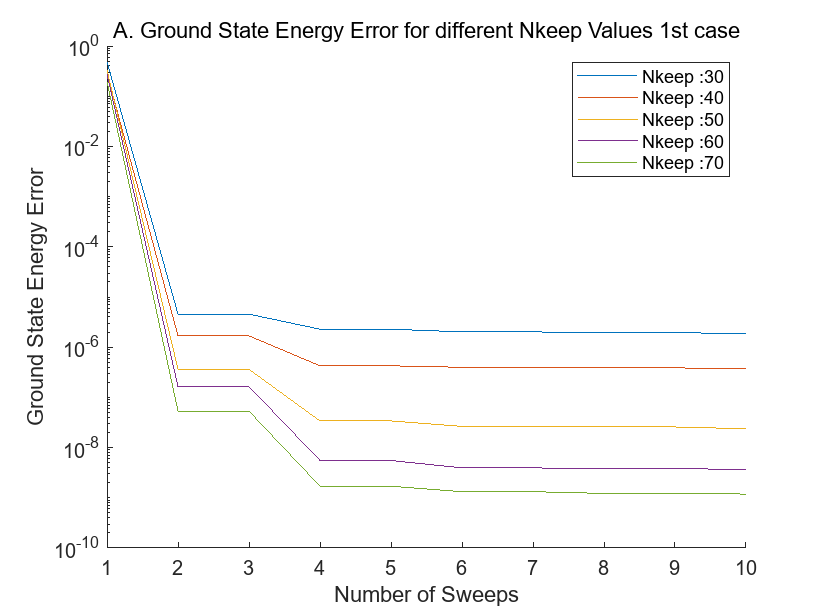


hold off;
yscale('log');
legend show;

title('A. Ground State Energy Error for different Nkeep Values 1st case');
xlabel('Number of Sweeps');
ylabel('Ground State Energy Error');

Now for random MPS and 1 site update:

figure;
hold on;
for i = 1 : 5
    N_keep = N_keep_list(i);
    fprintf('Nkeep value : %d', N_keep);
    [M, E_G1, E_list] = my_dmrg(MPO, N_keep, N_sweep, 1, 1, L, physical_dim); %random generated MPS, 1 site update dmrg
    [E_G2,d_G,e_1p] = nonIntTB (-t_a);
    Error_list = abs(E_list(end, :)- E_G2);
    plot(1:N_sweep*2, Error_list, 'DisplayName', ['Nkeep :', num2str(N_keep)]);
end

Nkeep value : 30

25-05-20 14:06:27 | Sweep #1 of 10 (right -> left) : Energy = -23.39265
25-05-20 14:06:27 | Sweep #2 of 10 (left -> right) : Energy = -25.03686
25-05-20 14:06:27 | Sweep #3 of 10 (right -> left) : Energy = -25.10362
25-05-20 14:06:28 | Sweep #4 of 10 (left -> right) : Energy = -25.10766
25-05-20 14:06:28 | Sweep #5 of 10 (right -> left) : Energy = -25.10779
25-05-20 14:06:28 | Sweep #6 of 10 (left -> right) : Energy = -25.10779
25-05-20 14:06:28 | Sweep #7 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:28 | Sweep #8 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:28 | Sweep #9 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:28 | Sweep #10 of 10 (left -> right) : Energy = -25.1078


Nkeep value : 40

25-05-20 14:06:29 | Sweep #1 of 10 (right -> left) : Energy = -23.62091
25-05-20 14:06:29 | Sweep #2 of 10 (left -> right) : Energy = -25.02481
25-05-20 14:06:29 | Sweep #3 of 10 (right -> left) : Energy = -25.09087
25-05-20 14:06:29 | Sweep #4 of 10 (left -> right) : Energy = -25.10643
25-05-20 14:06:29 | Sweep #5 of 10 (right -> left) : Energy = -25.10778
25-05-20 14:06:30 | Sweep #6 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:30 | Sweep #7 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:30 | Sweep #8 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:30 | Sweep #9 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:30 | Sweep #10 of 10 (left -> right) : Energy = -25.1078


Nkeep value : 50

25-05-20 14:06:31 | Sweep #1 of 10 (right -> left) : Energy = -23.86936
25-05-20 14:06:31 | Sweep #2 of 10 (left -> right) : Energy = -25.07601
25-05-20 14:06:31 | Sweep #3 of 10 (right -> left) : Energy = -25.10714
25-05-20 14:06:31 | Sweep #4 of 10 (left -> right) : Energy = -25.10779
25-05-20 14:06:32 | Sweep #5 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:32 | Sweep #6 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:32 | Sweep #7 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:32 | Sweep #8 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:33 | Sweep #9 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:33 | Sweep #10 of 10 (left -> right) : Energy = -25.1078


Nkeep value : 60

25-05-20 14:06:33 | Sweep #1 of 10 (right -> left) : Energy = -23.44901
25-05-20 14:06:33 | Sweep #2 of 10 (left -> right) : Energy = -25.0461
25-05-20 14:06:34 | Sweep #3 of 10 (right -> left) : Energy = -25.10329
25-05-20 14:06:34 | Sweep #4 of 10 (left -> right) : Energy = -25.10775
25-05-20 14:06:34 | Sweep #5 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:35 | Sweep #6 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:35 | Sweep #7 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:35 | Sweep #8 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:35 | Sweep #9 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:36 | Sweep #10 of 10 (left -> right) : Energy = -25.1078


Nkeep value : 70

25-05-20 14:06:36 | Sweep #1 of 10 (right -> left) : Energy = -23.44267
25-05-20 14:06:36 | Sweep #2 of 10 (left -> right) : Energy = -25.07666
25-05-20 14:06:37 | Sweep #3 of 10 (right -> left) : Energy = -25.10487
25-05-20 14:06:37 | Sweep #4 of 10 (left -> right) : Energy = -25.10771
25-05-20 14:06:38 | Sweep #5 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:38 | Sweep #6 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:39 | Sweep #7 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:39 | Sweep #8 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:39 | Sweep #9 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:40 | Sweep #10 of 10 (left -> right) : Energy = -25.1078


fprintf('E_G_true = %.6g, d_G = %i\n',E_G2,d_G);

E_G_true = -25.1078, d_G = 1


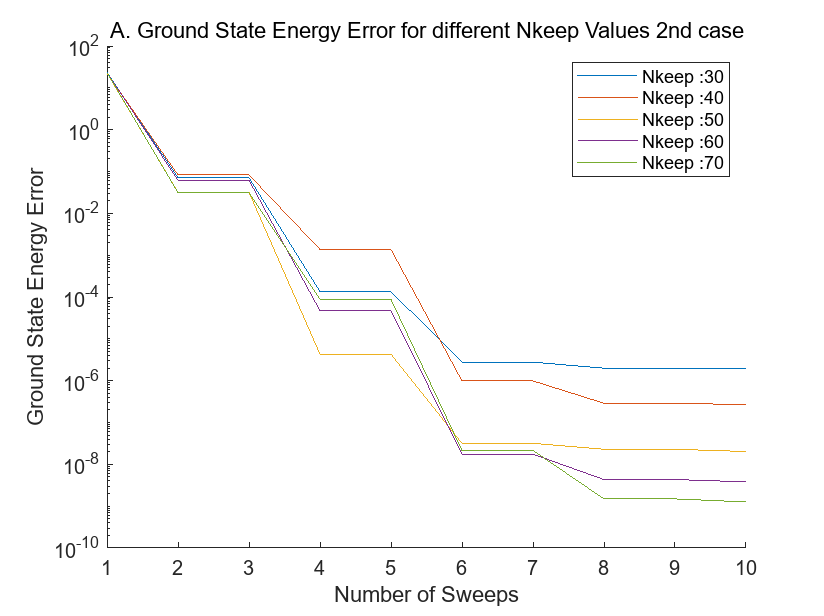


hold off;
yscale('log');
legend show;

title('A. Ground State Energy Error for different Nkeep Values 2nd case');
xlabel('Number of Sweeps');
ylabel('Ground State Energy Error');

for MPS by iterative diagonalization and 2 site update:

figure;
hold on;
for i = 1 : 5
    N_keep = N_keep_list(i);
    fprintf('Nkeep value : %d', N_keep);
    [M, E_G1, E_list] = my_dmrg(MPO, N_keep, N_sweep, 0, 2, L, physical_dim); %MPS by iterative diagonalization, 2 site update dmrg
    [E_G2,d_G,e_1p] = nonIntTB (-t_a);
    Error_list = abs(E_list(end, :)- E_G2);
    plot(1:N_sweep*2, Error_list, 'DisplayName', ['Nkeep :', num2str(N_keep)]);
end

Nkeep value : 30

25-05-20 14:06:54 | Sweep #1 of 10 (right -> left) : Energy = -25.10774
25-05-20 14:06:55 | Sweep #2 of 10 (left -> right) : Energy = -25.10779
25-05-20 14:06:55 | Sweep #3 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:55 | Sweep #4 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:55 | Sweep #5 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:55 | Sweep #6 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:56 | Sweep #7 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:56 | Sweep #8 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:56 | Sweep #9 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:56 | Sweep #10 of 10 (left -> right) : Energy = -25.1078


Nkeep value : 40

25-05-20 14:06:57 | Sweep #1 of 10 (right -> left) : Energy = -25.10774
25-05-20 14:06:57 | Sweep #2 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:57 | Sweep #3 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:58 | Sweep #4 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:58 | Sweep #5 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:58 | Sweep #6 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:59 | Sweep #7 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:59 | Sweep #8 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:06:59 | Sweep #9 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:06:59 | Sweep #10 of 10 (left -> right) : Energy = -25.1078


Nkeep value : 50

25-05-20 14:07:00 | Sweep #1 of 10 (right -> left) : Energy = -25.10779
25-05-20 14:07:00 | Sweep #2 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:07:01 | Sweep #3 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:01 | Sweep #4 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:07:01 | Sweep #5 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:02 | Sweep #6 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:07:02 | Sweep #7 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:03 | Sweep #8 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:07:03 | Sweep #9 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:03 | Sweep #10 of 10 (left -> right) : Energy = -25.1078


Nkeep value : 60

25-05-20 14:07:04 | Sweep #1 of 10 (right -> left) : Energy = -25.10779
25-05-20 14:07:05 | Sweep #2 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:07:05 | Sweep #3 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:05 | Sweep #4 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:07:06 | Sweep #5 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:06 | Sweep #6 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:07:06 | Sweep #7 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:07 | Sweep #8 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:07:07 | Sweep #9 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:07 | Sweep #10 of 10 (left -> right) : Energy = -25.1078


Nkeep value : 70

25-05-20 14:07:08 | Sweep #1 of 10 (right -> left) : Energy = -25.10779
25-05-20 14:07:09 | Sweep #2 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:07:09 | Sweep #3 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:09 | Sweep #4 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:07:10 | Sweep #5 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:10 | Sweep #6 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:07:11 | Sweep #7 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:11 | Sweep #8 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:07:12 | Sweep #9 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:13 | Sweep #10 of 10 (left -> right) : Energy = -25.1078


fprintf('E_G_true = %.6g, d_G = %i\n',E_G2,d_G);

E_G_true = -25.1078, d_G = 1


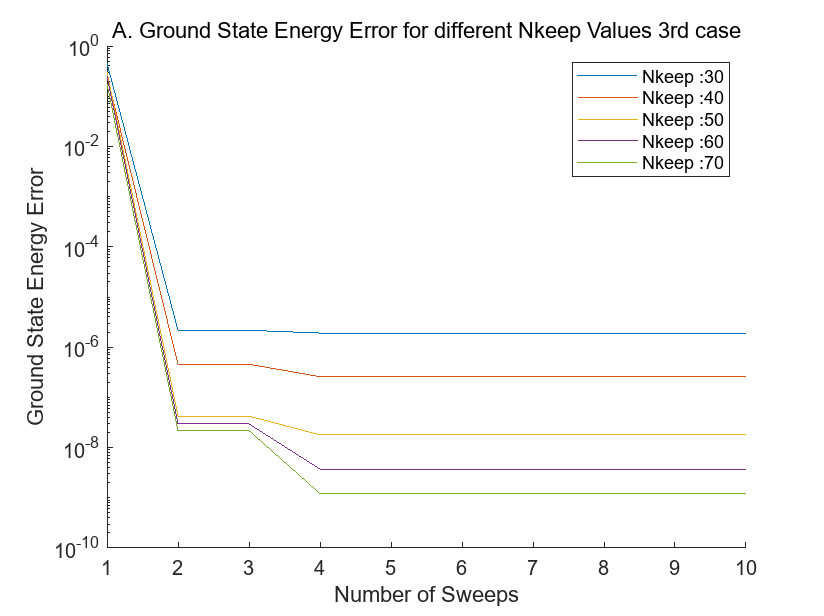


hold off;
yscale('log');
legend show;

title('A. Ground State Energy Error for different Nkeep Values 3rd case');
xlabel('Number of Sweeps');
ylabel('Ground State Energy Error');

Lastly, for random MPS and 2 site update:

figure;
hold on;
for i = 1 : 5
    N_keep = N_keep_list(i);
    fprintf('Nkeep value : %d', N_keep);
    [M, E_G1, E_list] = my_dmrg(MPO, N_keep, N_sweep, 1, 2, L, physical_dim); %random MPS, 2 site update dmrg
    [E_G2,d_G,e_1p] = nonIntTB (-t_a);
    Error_list = abs(E_list(end, :)- E_G2);
    plot(1:N_sweep*2, Error_list, 'DisplayName', ['Nkeep :', num2str(N_keep)]);
end

Nkeep value : 30

25-05-20 14:07:25 | Sweep #1 of 10 (right -> left) : Energy = -23.45252
25-05-20 14:07:25 | Sweep #2 of 10 (left -> right) : Energy = -25.02248
25-05-20 14:07:25 | Sweep #3 of 10 (right -> left) : Energy = -25.09735
25-05-20 14:07:25 | Sweep #4 of 10 (left -> right) : Energy = -25.10748
25-05-20 14:07:26 | Sweep #5 of 10 (right -> left) : Energy = -25.10779
25-05-20 14:07:26 | Sweep #6 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:07:26 | Sweep #7 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:26 | Sweep #8 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:07:27 | Sweep #9 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:27 | Sweep #10 of 10 (left -> right) : Energy = -25.1078


Nkeep value : 40

25-05-20 14:07:27 | Sweep #1 of 10 (right -> left) : Energy = -23.89525
25-05-20 14:07:27 | Sweep #2 of 10 (left -> right) : Energy = -25.08259
25-05-20 14:07:28 | Sweep #3 of 10 (right -> left) : Energy = -25.10726
25-05-20 14:07:28 | Sweep #4 of 10 (left -> right) : Energy = -25.10779
25-05-20 14:07:28 | Sweep #5 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:29 | Sweep #6 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:07:29 | Sweep #7 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:29 | Sweep #8 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:07:29 | Sweep #9 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:30 | Sweep #10 of 10 (left -> right) : Energy = -25.1078


Nkeep value : 50

25-05-20 14:07:30 | Sweep #1 of 10 (right -> left) : Energy = -24.48219
25-05-20 14:07:30 | Sweep #2 of 10 (left -> right) : Energy = -25.04447
25-05-20 14:07:31 | Sweep #3 of 10 (right -> left) : Energy = -25.10536
25-05-20 14:07:31 | Sweep #4 of 10 (left -> right) : Energy = -25.10776
25-05-20 14:07:31 | Sweep #5 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:32 | Sweep #6 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:07:32 | Sweep #7 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:32 | Sweep #8 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:07:33 | Sweep #9 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:33 | Sweep #10 of 10 (left -> right) : Energy = -25.1078


Nkeep value : 60

25-05-20 14:07:34 | Sweep #1 of 10 (right -> left) : Energy = -23.82095
25-05-20 14:07:35 | Sweep #2 of 10 (left -> right) : Energy = -25.06048
25-05-20 14:07:36 | Sweep #3 of 10 (right -> left) : Energy = -25.09903
25-05-20 14:07:36 | Sweep #4 of 10 (left -> right) : Energy = -25.10742
25-05-20 14:07:37 | Sweep #5 of 10 (right -> left) : Energy = -25.10779
25-05-20 14:07:37 | Sweep #6 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:07:38 | Sweep #7 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:39 | Sweep #8 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:07:39 | Sweep #9 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:40 | Sweep #10 of 10 (left -> right) : Energy = -25.1078


Nkeep value : 70

25-05-20 14:07:41 | Sweep #1 of 10 (right -> left) : Energy = -23.60216
25-05-20 14:07:42 | Sweep #2 of 10 (left -> right) : Energy = -25.0856
25-05-20 14:07:43 | Sweep #3 of 10 (right -> left) : Energy = -25.10656
25-05-20 14:07:44 | Sweep #4 of 10 (left -> right) : Energy = -25.10776
25-05-20 14:07:44 | Sweep #5 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:45 | Sweep #6 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:07:46 | Sweep #7 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:47 | Sweep #8 of 10 (left -> right) : Energy = -25.1078
25-05-20 14:07:47 | Sweep #9 of 10 (right -> left) : Energy = -25.1078
25-05-20 14:07:48 | Sweep #10 of 10 (left -> right) : Energy = -25.1078


fprintf('E_G_true = %.6g, d_G = %i\n',E_G2,d_G);

E_G_true = -25.1078, d_G = 1


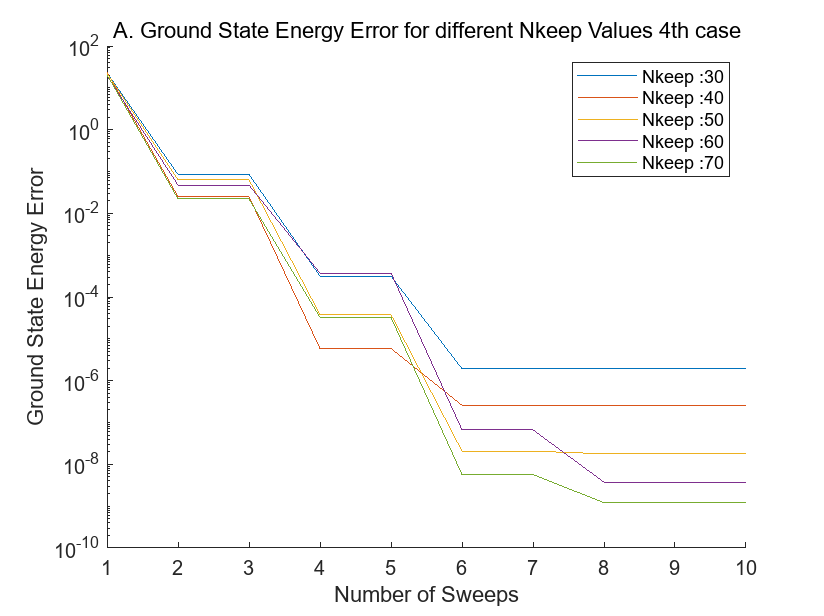


hold off;
yscale('log');
legend show;

title('A. Ground State Energy Error for different Nkeep Values 4th case');
xlabel('Number of Sweeps');
ylabel('Ground State Energy Error');

For the case of uniform hopping coefficients, only a few sweeps were required to reach the ground-state energy. As expected, a higher value of N_keep reduced the error overall. More sweeps were needed when using a random MPS compared to an MPS generated via iterative diagonalization. There was no significant difference observed between the single-site and two-site update methods.

Now, sub-problem b: use t_b for t list and repeat!

I suppressed the results obtained during the process from now on.

MPO = tb_chain_MPO(L, t_b);

fprintf('Sub-problem b, 1st case:')

Sub-problem b, 1st case:

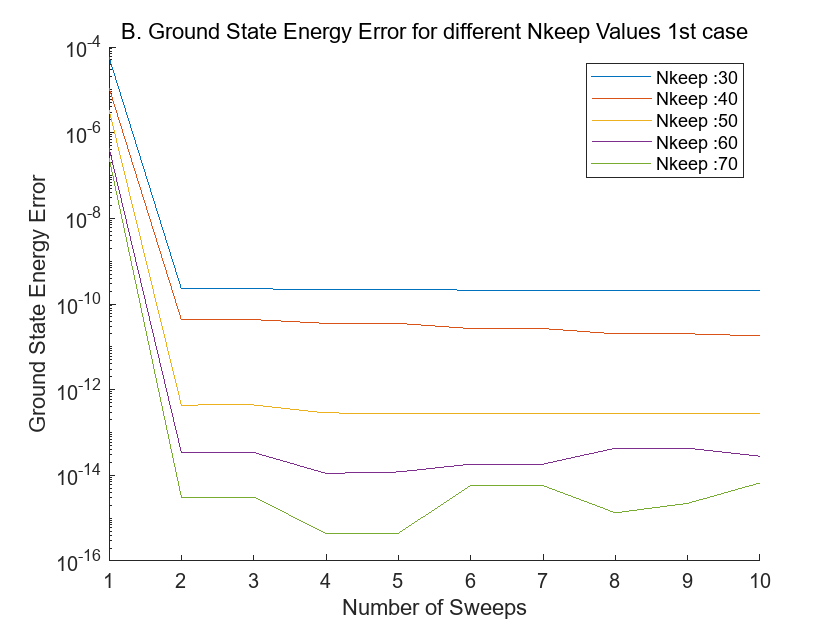

figure;
hold on;
for i = 1 : 5
    N_keep = N_keep_list(i);
    [~, M, E_G1, E_list] = evalc('my_dmrg(MPO, N_keep, N_sweep, 0, 1, L, physical_dim)'); %MPS by iterative diagonalization, 1 site update dmrg
    [E_G2,d_G,e_1p] = nonIntTB (-t_b);
    Error_list = abs(E_list(end, :)- E_G2);
    plot(1:N_sweep*2, Error_list, 'DisplayName', ['Nkeep :', num2str(N_keep)]);
end

hold off;
yscale('log');
legend show;

title('B. Ground State Energy Error for different Nkeep Values 1st case');
xlabel('Number of Sweeps');
ylabel('Ground State Energy Error');

fprintf('Sub-problem b, 2nd case:')

Sub-problem b, 2nd case:

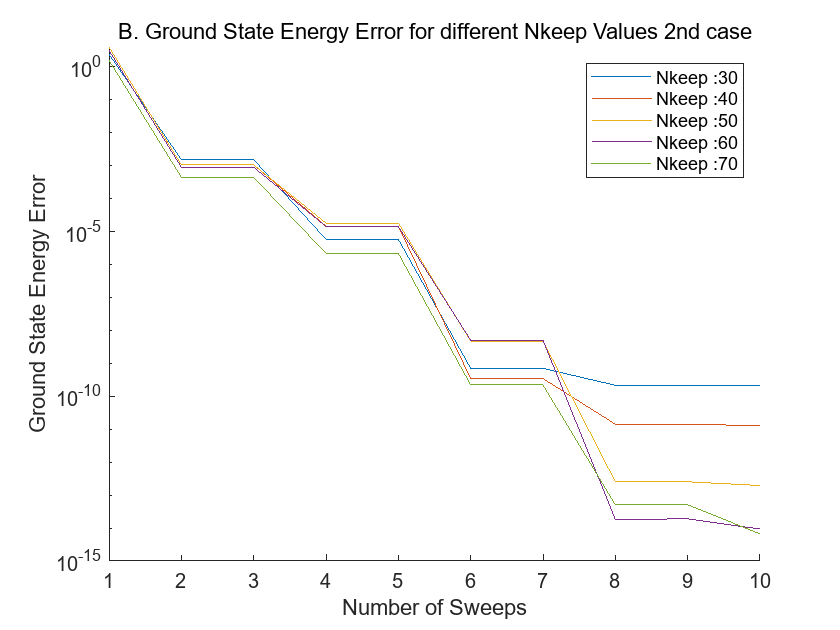

figure;
hold on;
for i = 1 : 5
    N_keep = N_keep_list(i);
    [~, M, E_G1, E_list] = evalc('my_dmrg(MPO, N_keep, N_sweep, 1, 1, L, physical_dim)'); %random generated MPS, 1 site update dmrg
    [E_G2,d_G,e_1p] = nonIntTB (-t_b);
    Error_list = abs(E_list(end, :)- E_G2);
    plot(1:N_sweep*2, Error_list, 'DisplayName', ['Nkeep :', num2str(N_keep)]);
end


hold off;
yscale('log');
legend show;

title('B. Ground State Energy Error for different Nkeep Values 2nd case');
xlabel('Number of Sweeps');
ylabel('Ground State Energy Error');

fprintf('Sub-problem b, 3rd case:')

Sub-problem b, 3rd case:

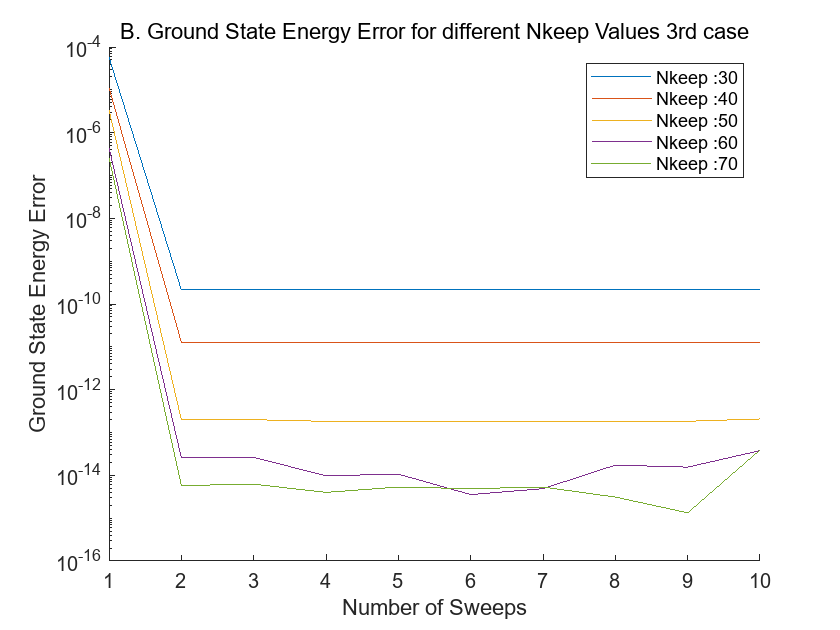

figure;
hold on;
for i = 1 : 5
    N_keep = N_keep_list(i);
    [~, M, E_G1, E_list] = evalc('my_dmrg(MPO, N_keep, N_sweep, 0, 2, L, physical_dim)'); %MPS by iterative diagonalization, 2 site update dmrg
    [E_G2,d_G,e_1p] = nonIntTB (-t_b);
    Error_list = abs(E_list(end, :)- E_G2);
    plot(1:N_sweep*2, Error_list, 'DisplayName', ['Nkeep :', num2str(N_keep)]);
end

hold off;
yscale('log');
legend show;

title('B. Ground State Energy Error for different Nkeep Values 3rd case');
xlabel('Number of Sweeps');
ylabel('Ground State Energy Error');

fprintf('Sub-problem b, 4th case:')

Sub-problem b, 4th case:

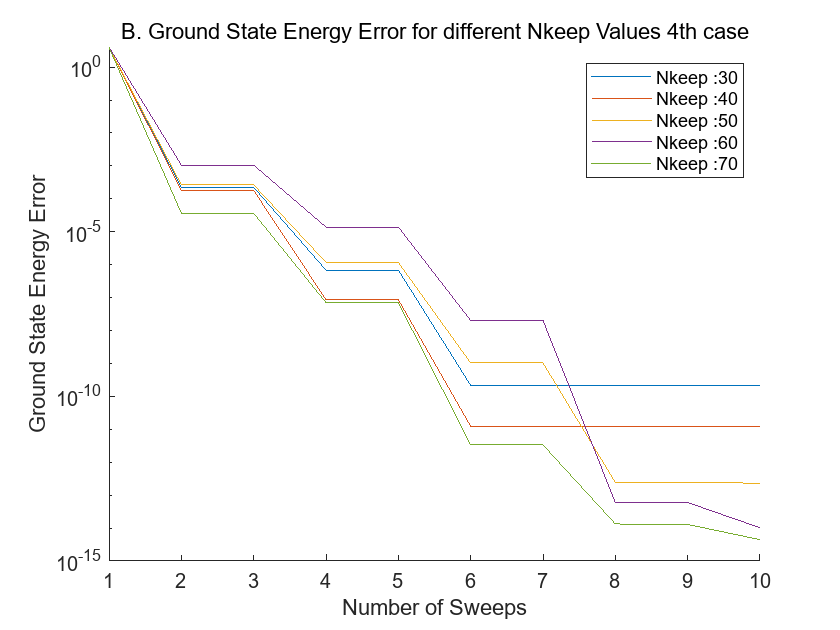

figure;
hold on;
for i = 1 : 5
    N_keep = N_keep_list(i);
    [~, M, E_G1, E_list] = evalc('my_dmrg(MPO, N_keep, N_sweep, 1, 2, L, physical_dim)'); %random MPS, 2 site update dmrg
    [E_G2,d_G,e_1p] = nonIntTB (-t_b);
    Error_list = abs(E_list(end, :)- E_G2);
    plot(1:N_sweep*2, Error_list, 'DisplayName', ['Nkeep :', num2str(N_keep)]);
end


hold off;
yscale('log');
legend show;

title('B. Ground State Energy Error for different Nkeep Values 4th case');
xlabel('Number of Sweeps');
ylabel('Ground State Energy Error');

In sub-problem (b), overall errors were lower compared to the uniform case. Due to the already low error, a slight increase in error was observed over the course of sweeps at higher N_keep values, but these variations were negligible. Other results were consistent with the observations from sub-problem (a).

For sub-problem c , do it again!

MPO = tb_chain_MPO(L, t_c);
fprintf('Sub-problem c, 1st case:')

Sub-problem c, 1st case:

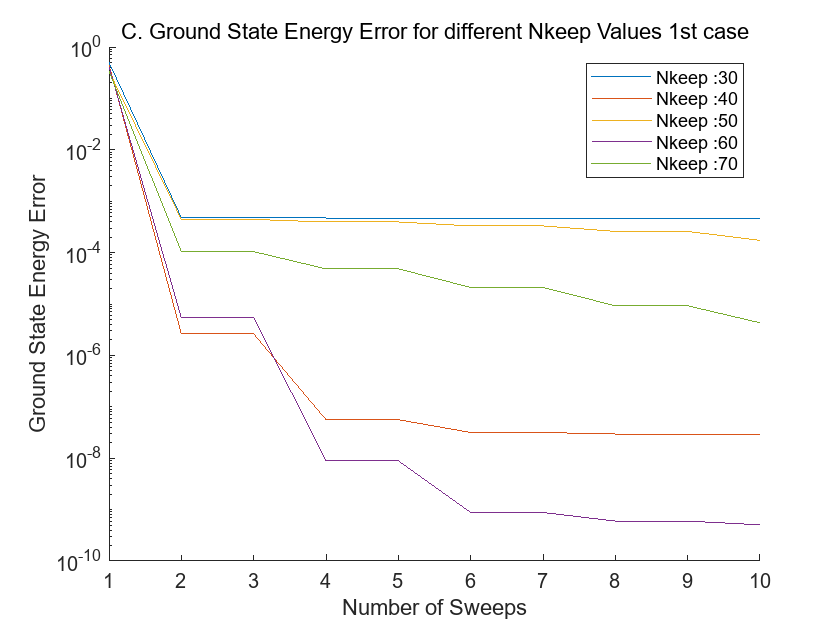

figure;
hold on;
for i = 1 : 5
    N_keep = N_keep_list(i);
    [~, M, E_G1, E_list] = evalc('my_dmrg(MPO, N_keep, N_sweep, 0, 1, L, physical_dim)'); %MPS by iterative diagonalization, 1 site update dmrg
    [E_G2,d_G,e_1p] = nonIntTB (-t_c);
    Error_list = abs(E_list(end, :)- E_G2);
    plot(1:N_sweep*2, Error_list, 'DisplayName', ['Nkeep :', num2str(N_keep)]);
end

hold off;
yscale('log');
legend show;

title('C. Ground State Energy Error for different Nkeep Values 1st case');
xlabel('Number of Sweeps');
ylabel('Ground State Energy Error');

fprintf('Sub-problem c, 2nd case:')

Sub-problem c, 2nd case:

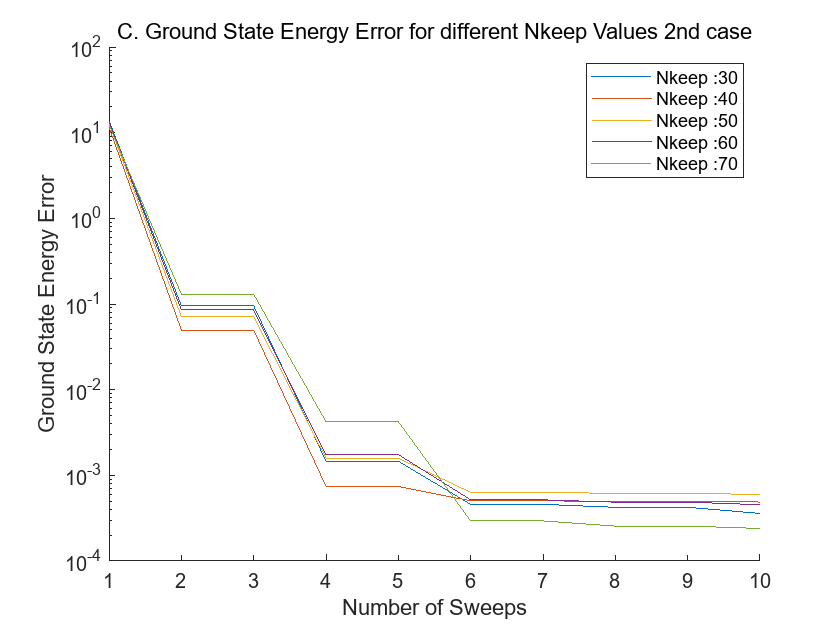

figure;
hold on;
for i = 1 : 5
    N_keep = N_keep_list(i);
    [~, M, E_G1, E_list] = evalc('my_dmrg(MPO, N_keep, N_sweep, 1, 1, L, physical_dim)'); %random generated MPS, 1 site update dmrg
    [E_G2,d_G,e_1p] = nonIntTB (-t_c);
    Error_list = abs(E_list(end, :)- E_G2);
    plot(1:N_sweep*2, Error_list, 'DisplayName', ['Nkeep :', num2str(N_keep)]);
end


hold off;
yscale('log');
legend show;

title('C. Ground State Energy Error for different Nkeep Values 2nd case');
xlabel('Number of Sweeps');
ylabel('Ground State Energy Error');

fprintf('Sub-problem c, 3rd case:')

Sub-problem c, 3rd case:

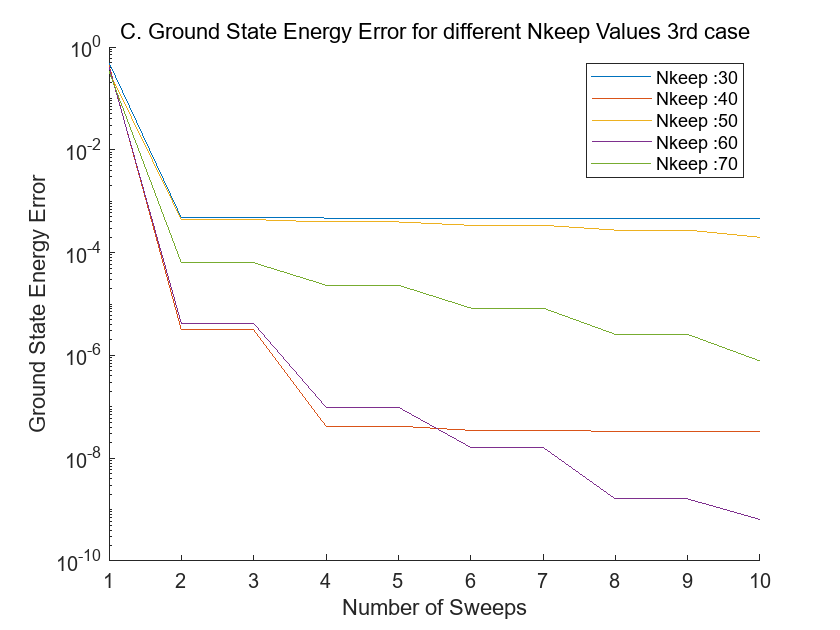

figure;
hold on;
for i = 1 : 5
    N_keep = N_keep_list(i);
    [~, M, E_G1, E_list] = evalc('my_dmrg(MPO, N_keep, N_sweep, 0, 2, L, physical_dim)'); %MPS by iterative diagonalization, 2 site update dmrg
    [E_G2,d_G,e_1p] = nonIntTB (-t_c);
    Error_list = abs(E_list(end, :)- E_G2);
    plot(1:N_sweep*2, Error_list, 'DisplayName', ['Nkeep :', num2str(N_keep)]);
end

hold off;
yscale('log');
legend show;

title('C. Ground State Energy Error for different Nkeep Values 3rd case');
xlabel('Number of Sweeps');
ylabel('Ground State Energy Error');

fprintf('Sub-problem c, 4th case:')

Sub-problem c, 4th case:

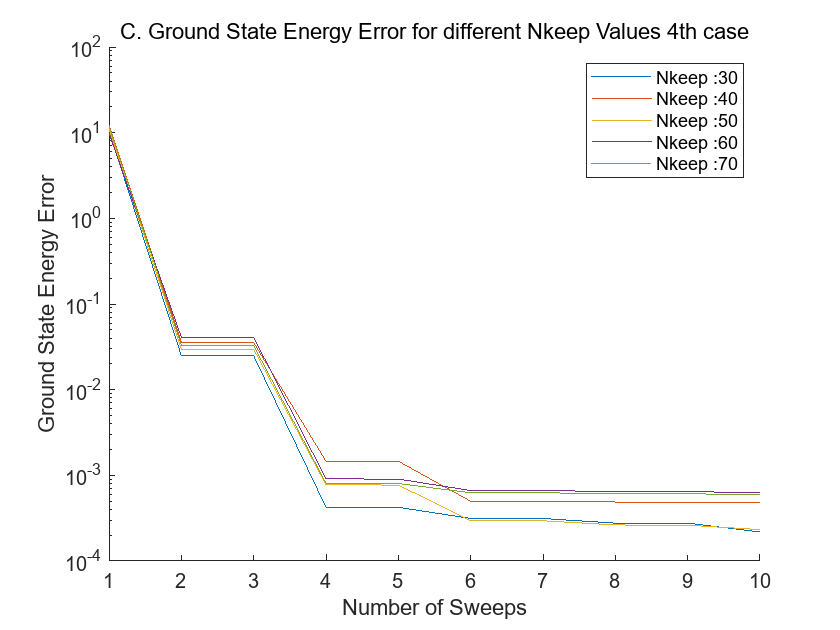

figure;
hold on;
for i = 1 : 5
    N_keep = N_keep_list(i);
    [~, M, E_G1, E_list] = evalc('my_dmrg(MPO, N_keep, N_sweep, 1, 2, L, physical_dim)'); %random MPS, 2 site update dmrg
    [E_G2,d_G,e_1p] = nonIntTB (-t_c);
    Error_list = abs(E_list(end, :)- E_G2);
    plot(1:N_sweep*2, Error_list, 'DisplayName', ['Nkeep :', num2str(N_keep)]);
end


hold off;
yscale('log');
legend show;

title('C. Ground State Energy Error for different Nkeep Values 4th case');
xlabel('Number of Sweeps');
ylabel('Ground State Energy Error');

In sub-problem (c), the errors varied the most among the three cases. For random MPS, the error decreased only up to a certain point and did not improve further even as N_keep increased. In contrast, for MPS generated via iterative diagonalization, the error significantly decreased with higher N_keep values. Again, no notable difference was observed between the single-site and two-site update methods.